clc
close all
clear all
cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../';
currentfolder = 'toy_exp_50_0.5/'

currentfolder = 'toy_exp_50_0.5/'

index = 0

index = 0

index_s = int2str(index)

index_s = '0'

V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';

V10 = pcread(append(rootfolder,'demo_data/example_1.pcd'))';
V20 = pcread(append(rootfolder,'demo_data/example_2.pcd'))';
V30 = pcread(append(rootfolder,'demo_data/example_3.pcd'))';
V40 = pcread(append(rootfolder,'demo_data/example_4.pcd'))';

V = {V1,V2,V3,V4}';
V0 = {V10,V20,V30,V40}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};
Point_inlier = {}


Point_inlier =

  0×0 empty cell array



Point_outlier = {}


Point_outlier =

  0×0 empty cell array



Point_original = {}


Point_original =

  0×0 empty cell array



gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../toy_exp_50_0.5/0/gt_poses.txt'

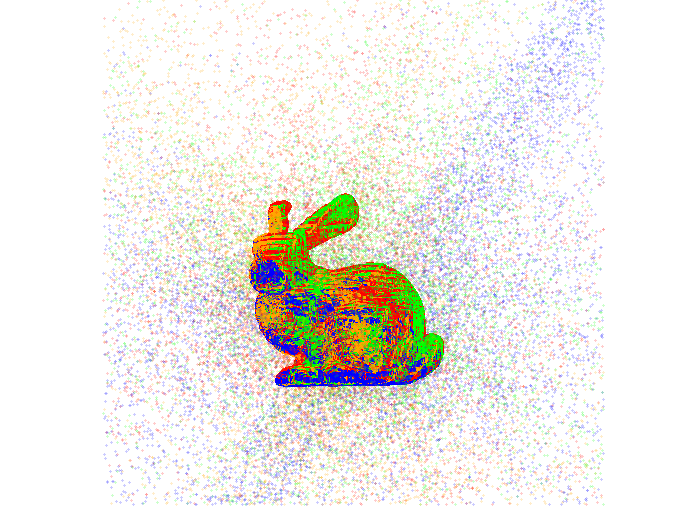

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
for i=1:4
    Tcvo{i} = inv(Tcvo{i});
end
for i=1:4
    T = Tcvo{i};
    locaiton = V{i}.Location;
    locaiton = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
%     size(locaiton)
    color =  V{i}.Color;
    [h w] = size(locaiton);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    for j=1:h
        if color(j,:) == [255 0 0]
            inlier(j,:) = locaiton(j,:);
        else
            outlier(j,:) = locaiton(j,:);
        end

    end
    Point_inlier{i} = inlier;
    Point_outlier{i} = outlier;
    Point_original{i} = V0{i}.Location;
   
end
figure(1)
for i=1:4

    scatter3(Point_original{i}(:,1),Point_original{i}(:,2),Point_original{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier{i}(:,1),Point_outlier{i}(:,2),Point_outlier{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
%axis([-50 50 -50 50 -50 50 ])
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-0.214 0.192])
ylim([-0.064 0.346])
zlim([-0.158 0.226])
view([0.964 90.000])

hold off

## Before


cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/';
currentfolder = 'toy_exp_50_0.5/'

currentfolder = 'toy_exp_50_0.5/'

index = 24

index = 24

index_s = int2str(index)

index_s = '24'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/toy_exp_50_0.5/24/gt_poses.txt'

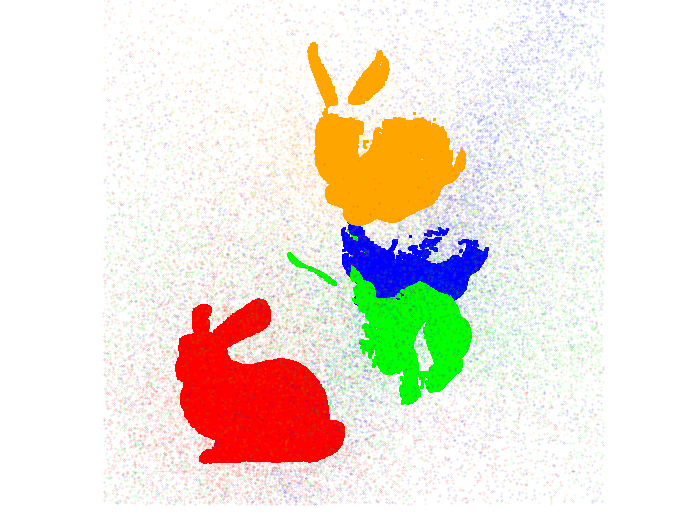

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% for i=1:4
%     Tcvo{i} = inv(Tcvo{i});
% end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tcvo{i};
    location = Point_outlier{i};
    locaiton = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
%     size(locaiton)
   
    [h w] = size(locaiton);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_outlier_cur{i} = locaiton;
   
end
figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.1)
    axis equal
    grid off 
    axis off
   

end
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-0.214 0.192])
ylim([-0.064 0.346])
zlim([-0.158 0.226])
view([0.964 90.000])
hold off

## Cvo result


cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/';
currentfolder = 'toy_exp_50_0.5/'

currentfolder = 'toy_exp_50_0.5/'

index = 24

index = 24

index_s = int2str(index)

index_s = '24'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/toy_exp_50_0.5/24/gt_poses.txt'

A = readmatrix(gtfilename);
Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_results.txt')

gtfilename = '../../exp/toy_exp_50_0.5/24/rkhs_results.txt'

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% for i=1:4
%     Tcvo{i} = inv(Tcvo{i});
% end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tgtr{i};
    T_c = Tcvo{i}
    location = Point_outlier{i};
    location = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
    location = bsxfun(@plus,T_c(1:3,1:3) *location',T_c(1:3,4))';
%     size(locaiton)
     Point_outlier_cur{i} = location;
    [h w] = size(location);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_original_cur{i} = bsxfun(@plus,T_c(1:3,1:3) * Point_original_cur{i}',T_c(1:3,4))';
  

   
end

T_c =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_c =     0.5836    0.2756   -0.7638   -0.0559
   -0.1975    0.9606    0.1956   -0.0563
    0.7876    0.0367    0.6150   -0.1410
         0         0         0    1.0000


T_c =     0.8818    0.2237   -0.4153   -0.1352
    0.1177    0.7482    0.6529   -0.1502
    0.4568   -0.6246    0.6334    0.0511
         0         0         0    1.0000


T_c =     0.9395   -0.0040   -0.3426   -0.0112
    0.1990    0.8203    0.5361   -0.3394
    0.2789   -0.5719    0.7715   -0.0367
         0         0         0    1.0000


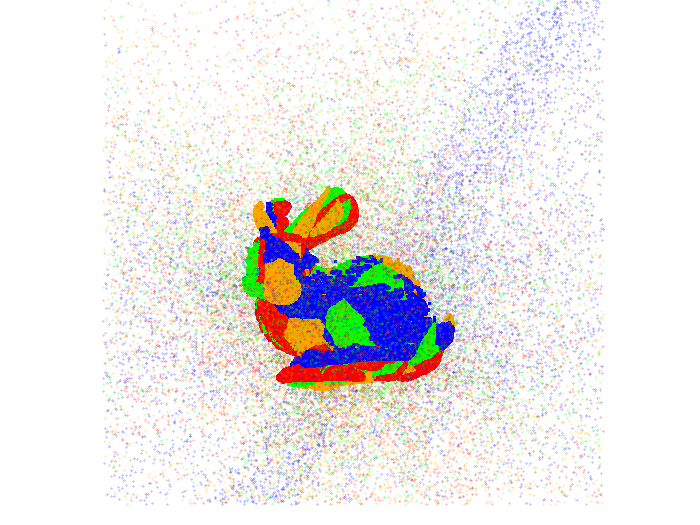

figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-0.214 0.192])
ylim([-0.064 0.346])
zlim([-0.158 0.226])
view([0.964 90.000])
hold off

## cvo semantics

% 
% cla
% fprintf(' Data loading...\n');
% % load gt
% rootfolder = '../../exp/tartanair_full_semantic/';
% currentfolder = 'tartanair_toy_exp_50_0.5/'
% index = 2
% index_s = int2str(index)
% 
% figure(1)
% colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};
% 
% gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')
% A = readmatrix(gtfilename);
% Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_results.txt')
% A = readmatrix(gtfilename);
% Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
% % for i=1:4
% %     Tcvo{i} = inv(Tcvo{i});currentfolder = 'toy_exp_50_0.375/'
index = 4
% % end
% Point_outlier_cur= {};
% Point_original_cur = {};
% for i=1:4
%     T = Tgtr{i};
%     T_c = Tcvo{i}
%     location = Point_outlier{i};
%     location = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
%     location = bsxfun(@plus,T_c(1:3,1:3) *location',T_c(1:3,4))';
% %     size(locaiton)
%      Point_outlier_cur{i} = location;
%     [h w] = size(location);
%     inlier = zeros(h,w);
%     outlier =  zeros(h,w);
%     Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
%     Point_original_cur{i} = bsxfun(@plus,T_c(1:3,1:3) * Point_original_cur{i}',T_c(1:3,4))';
%   
% 
%    
% end
% figure(1)
% for i=1:4
% 
%     scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
%     hold on 
%     scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
%     axis equal
%     grid off 
%     axis off
%    
% 
% end
% set(gca,'LooseInset',get(gca,'TightInset'));
%  pos = get(gca, 'Position');
%     pos(1) = 0.055;
%     pos(3) = 0.9;
%     set(gca, 'Position', pos)
% xlim([-0.214 0.192])
% ylim([-0.064 0.346])
% zlim([-0.158 0.226])
% view([0.964 90.000])
% hold off

## jrmpc

cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/';
currentfolder = 'toy_exp_50_0.5/'

currentfolder = 'toy_exp_50_0.5/'

index = 24

index = 24

index_s = int2str(index)

index_s = '24'


figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[255,165,0]};

gtfilename = append(rootfolder,currentfolder,index_s,'/gt_poses.txt')

gtfilename = '../../exp/toy_exp_50_0.5/24/gt_poses.txt'

A = readmatrix(gtfilename);
Tgtr = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
gtfilename = append(rootfolder,currentfolder,index_s,'/jrmpc.txt')

gtfilename = '../../exp/toy_exp_50_0.5/24/jrmpc.txt'

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';

for i=1:4
    Tcvo{i} = inv(Tcvo{1}) * Tcvo{i};
end
Point_outlier_cur= {};
Point_original_cur = {};
for i=1:4
    T = Tgtr{i};
    T_c = Tcvo{i}
    location = Point_outlier{i};
    location = bsxfun(@plus,T(1:3,1:3) *location',T(1:3,4))';
    location = bsxfun(@plus,T_c(1:3,1:3) *location',T_c(1:3,4))';
%     size(locaiton)
     Point_outlier_cur{i} = location;
    [h w] = size(location);
    inlier = zeros(h,w);
    outlier =  zeros(h,w);
    Point_original_cur{i} = bsxfun(@plus,T(1:3,1:3) * Point_original{i}',T(1:3,4))';
    Point_original_cur{i} = bsxfun(@plus,T_c(1:3,1:3) * Point_original_cur{i}',T_c(1:3,4))';
  

   
end

T_c =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T_c =    -0.1281   -0.9068    0.4015    0.0989
   -0.9072    0.2707    0.3220    0.1277
   -0.4007   -0.3230   -0.8574    0.2310
         0         0         0    1.0000


T_c =    -0.6567   -0.5619   -0.5030    0.2282
   -0.7405    0.6069    0.2888    0.0193
    0.1430    0.5621   -0.8146   -0.0259
         0         0         0    1.0000


T_c =    -0.6917   -0.6676   -0.2755    0.3355
   -0.7144    0.6884    0.1253   -0.0929
    0.1060    0.2835   -0.9531    0.2087
         0         0         0    1.0000


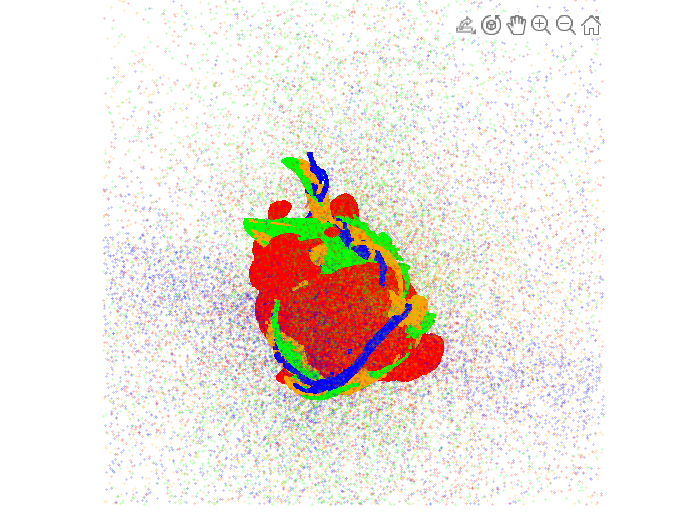

figure(1)
for i=1:4

    scatter3(Point_original_cur{i}(:,1),Point_original_cur{i}(:,2),Point_original_cur{i}(:,3),5,colormap{i}/255,'filled','MarkerFaceAlpha',1)
    hold on 
    scatter3(Point_outlier_cur{i}(:,1),Point_outlier_cur{i}(:,2),Point_outlier_cur{i}(:,3),2,colormap{i}/255,'filled','MarkerFaceAlpha',0.2)
    axis equal
    grid off 
    axis off
   

end
set(gca,'LooseInset',get(gca,'TightInset'));
 pos = get(gca, 'Position');
    pos(1) = 0.055;
    pos(3) = 0.9;
    set(gca, 'Position', pos)
xlim([-0.214 0.192])
ylim([-0.064 0.346])
zlim([-0.158 0.226])
view([0.964 90.000])
hold off